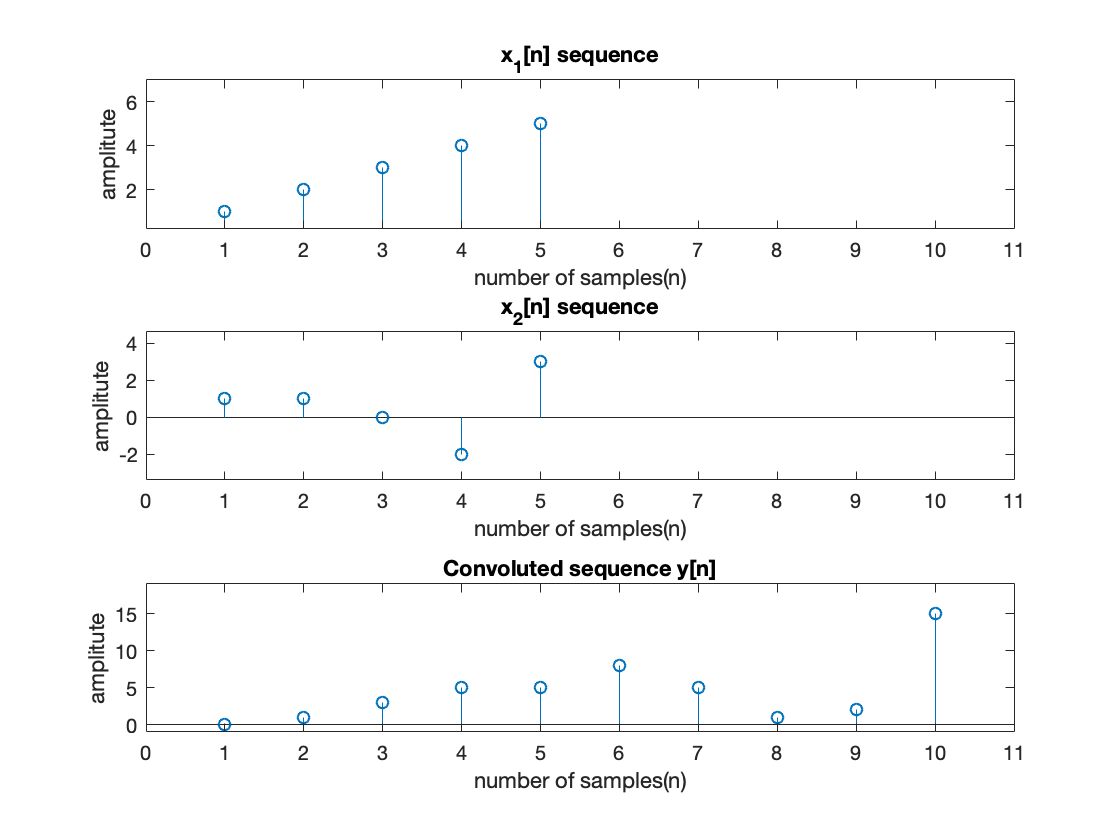

%----------------------------------------------------------------------
%Name : Sumit Patidar
%Roll no: B15237
%Task : program to perform linear convolution
%----------------------------------------------------------------------

close all;
clc;

%take sequence as an input 
%I am assuming sequence starts from n = 1
x1 = input('enter the sequence x1: '); %example input = [1 2 3 4 5]
x2 = input('enter the sequence x2: ');
x1_length = length(x1);
x2_length = length(x2);
n_length = x1_length + x2_length; %the size of convoluted signal which we will get
n1 = 1:1:x1_length;
n2 = 1:1:x2_length;
n = 1:1:n_length;

%plot sequence x1
p1 = subplot(3,1,1);
stem(n1, x1);
xlabel('number of samples(n)');
ylabel('amplitute');
title('x_1[n] sequence');
hold on;

%plot sequence x2
p2 = subplot(3,1,2);
stem(n2, x2);
xlabel('number of samples(n)');
ylabel('amplitute');
title('x_2[n] sequence');
hold on;

%perform linear convolution
%{ y[i] = x_1[i]*x_2[i]
%       = sum (x_1[k]*x_2[i-k]), for each i in range [1, n_length]
%                              , k lies in range [1, x1_length]  i.e where x_1 is defined
%    Note: where x2 is not defined, it is taken as zero
%}

y = zeros(1,n_length);
for i = 1:n_length
  for k = 1:length(x1)
        if ((i-k) <=0) || ((i-k) > x2_length)
            y(i) = y(i) + 0;
        else
            y(i) = y(i)  + x1(k)*x2(i-k);     
        end
  end
end

%plot the convoluted sequence
p3 = subplot(3,1,3);
stem(n, y);
xlabel('number of samples(n)');
ylabel('amplitute');
title('Convoluted sequence y[n]');

%setting axis limits to visualize better
axis(p1, [0  n_length+1 min(x1)*1.2-1 max(x1)*1.2+1]);
axis(p2, [0  n_length+1 min(x2)*1.2-1 max(x2)*1.2+1]);
axis(p3, [0  n_length+1 min(y)*1.2-1 max(y)*1.2+1]);


display(y);

y =      0     1     3     5     5     8     5     1     2    15


display(n);

n =      1     2     3     4     5     6     7     8     9    10
